# Method#1 Random Endpoints

## 隨機端點法

畫出單位圓和內接正三角形

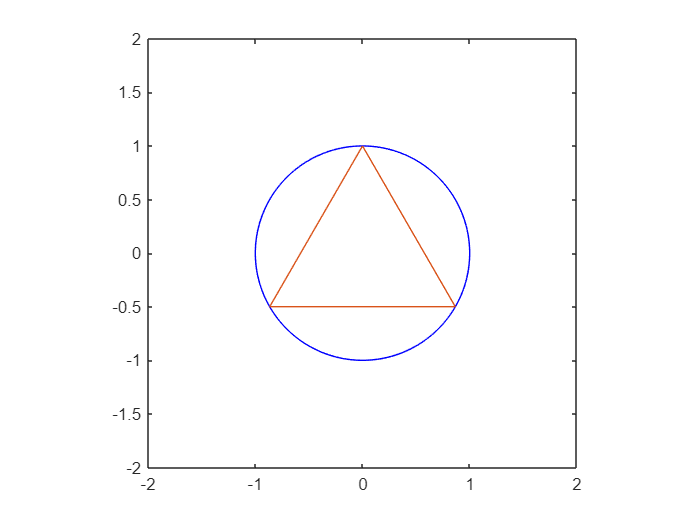

r = 1;
syms x y
fimplicit(x^2+y^2 == r^2, [-2 2, -2 2], 'b')
axis equal;
hold on
t = [0;1];
R = [cos(2*pi/3) -sin(2*pi/3); sin(2*pi/3) cos(2*pi/3)];
t = [t R*t R^2*t t]';
plot(t(:,1),t(:,2), 'Color', '#D95319')
hold off

## Probability

$N$：樣本數

$P$：機率

$a=\sqrt 3
$：正三角形邊長

$chord\_len$：算出來的弦長

### 顏色

圓形：藍色

內接三角形：橘色

圓上的點：紅色(實心)

- 有超過：綠色

- 沒超過：紅色

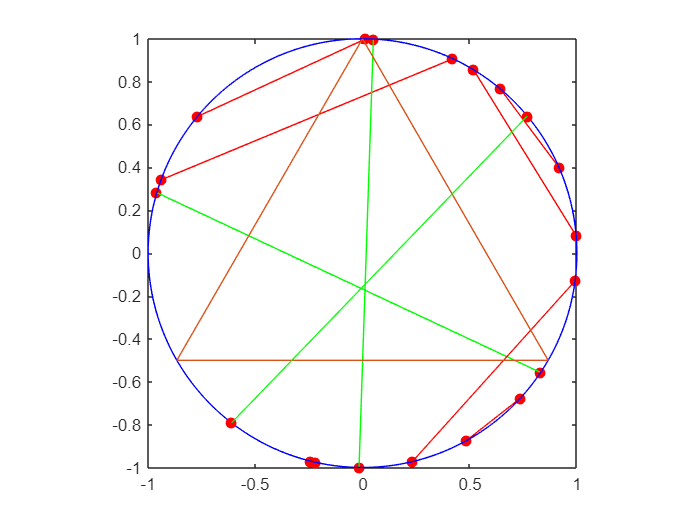

N = 10;        % 樣本數
a = sqrt(3);    % 三角形邊長
count = 0;      % 超過a的次數
for i = 1:N
    theta1 = rand(1)*2*pi;
    theta2 = rand(1)*2*pi;
    p1 = [cos(theta1) sin(theta1)]; % 點一
    p2 = [cos(theta2) sin(theta2)]; % 點二
    chord_len = sqrt((p1(1)-p2(1))^2 + ((p1(2)-p2(2))^2));
    
    % Plot
    fimplicit(x^2+y^2 == r^2, [-1 1 -1 1], 'b')
    hold on
    plot(t(:,1),t(:,2),'color', '#D95319');

    plot(p1(1), p1(2),'ro-', 'MarkerFaceColor', 'r')
    plot(p2(1), p2(2),'ro-', 'MarkerFaceColor', 'r')
    if chord_len >= a
        line([p1(1); p2(1)], [p1(2); p2(2)], 'color', 'g')  % 超過畫綠線
        count = count + 1;
    else
        line([p1(1); p2(1)], [p1(2); p2(2)], 'color', 'r')  % 沒超過畫紅線
    end
    axis equal;
%     hold off
%     pause(0.05)
end
hold off

N = 100000;
a = sqrt(3);
count = 0;
for i = 1:N
    theta1 = rand(1)*2*pi;
    theta2 = rand(1)*2*pi;
    p1 = [cos(theta1) sin(theta1)];
    p2 = [cos(theta2) sin(theta2)];
    chord_len = sqrt((p1(1)-p2(1))^2 + ((p1(2)-p2(2))^2));
    if chord_len >= a
        count = count + 1;
    end
end

P = count/N % 機率

P = 0.3332

弦分布

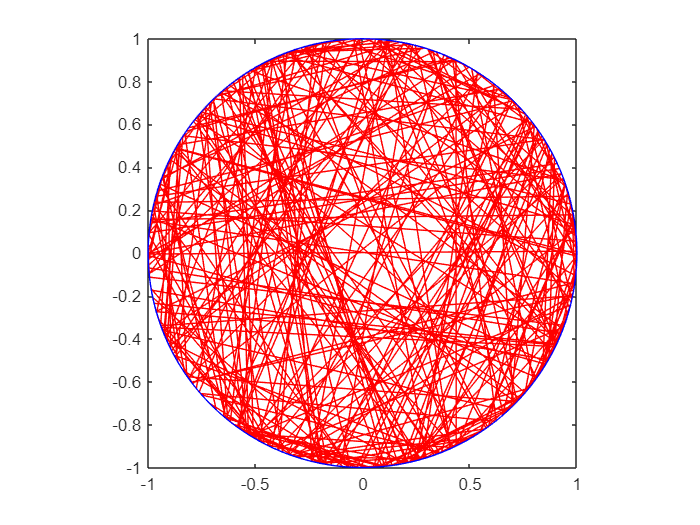

clf;
N = 300;
for i = 1:N
    fimplicit(x^2+y^2 == r^2, [-1 1 -1 1], 'b')
    hold on
    theta1 = rand(1)*2*pi;
    theta2 = rand(1)*2*pi;
    p1 = [cos(theta1) sin(theta1)];
    p2 = [cos(theta2) sin(theta2)];
    line([p1(1); p2(1)], [p1(2); p2(2)], 'color', 'r')
end
axis equal
hold off

中點分佈圖

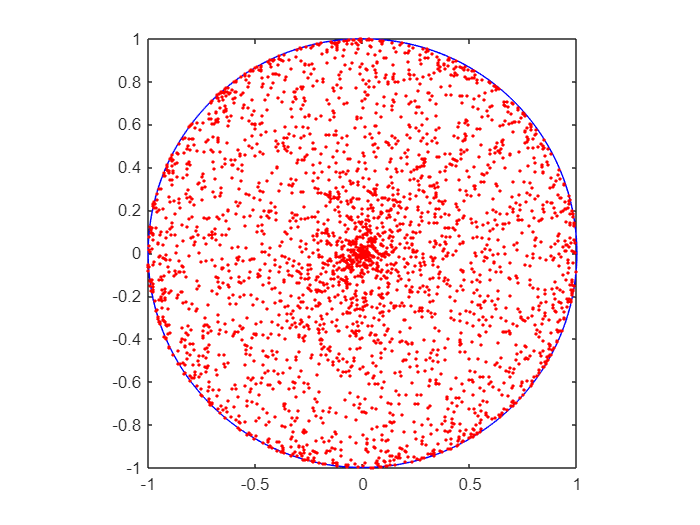

clf;
N = 3000;
theta = 2*pi*rand(N,2);
point = [(cos(theta(:,1))+cos(theta(:,2)))/2 (sin(theta(:,1))+sin(theta(:,2)))/2];
fimplicit(x^2+y^2 == r^2, [-1 1 -1 1], 'b')
hold on;
axis equal;
plot(point(:,1),point(:,2),'r.');
hold off;